# splWindows

A script to calculate a lobing pattern of tonal and broadband sound pressure level measurements at an array of hydrophones from a passing ship using its AIS track. 

By grouping all of the consecutive measurements along the ships track by same look angle (azimuth), the lobing characteristics of the ship's noise signature can be estimated. 

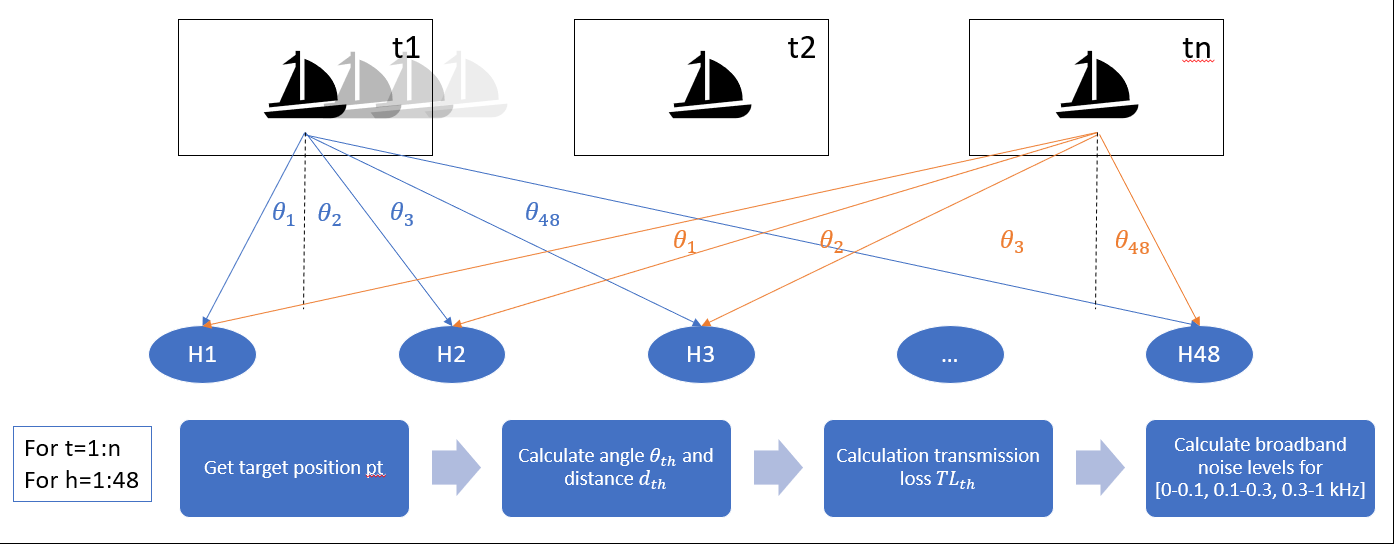

## Initialize

clearvars

#### Flip switches

tog.VOI = 'OcEnd-AAA2-30Aug';
tog.filetype = 'hdf5';
tog.sampling = 'full';
tog.calHph = 'no';
tog.plotSpec = 'yes';
tog.plotSpectra = 'yes';
tog.plotShipTrack = 'yes';
tog.plotBearingHistory = 'yes';
tog.plotSpatialSummary = 'yes';
tog.plotIntTrack = 'no';
tog.plotAspects = 'yes';
tog.plotMeans = 'yes';
tog.plotTonalTracker = 'yes';
tog.saveOn = 'no';

#### Set parameters

par = setPars;

## Acoustic data pre-processing

### Define gains

gain.sens = 194.5;                   % (nominal) dB re 1V/uPa
gain.amp = 0;                   % Amplifier gain 70 dB (adjustable), A/D -8 dB (I don't think gain is correct - confirm A/D)
gain.adc = 0;  %20*log(5/(2^16));    % 1 Vrms = 16 bit peak-to-peak --> could also be +/- 1 floating point range (20log(2.0/5.0))
gain.fft = 0;                   % FFT gain is applied in spectra (2/NFFT)

cal = 10^(gain.sens/20);             % hydrophone calibration

### Load acoustic data

[startTime, AOI, NWFile] = loader(tog.VOI);
switch tog.filetype
    case 'wav'
        [x,~] = audioread(NWFile,'native');  % What is this signal? Volts? --> need to convert to dB (x/gain.sens)
    case 'hdf5'
        load(NWFile);  % What is this signal? Volts? --> need to convert to dB (x/sens)
        %x = data';
        x = data;
        clear data;
end


SegLengthSamples = par.BinWidth*par.fs;
DataLengthSamples = par.numSegs*SegLengthSamples;

### Downsample acoustic data (optional)

switch tog.sampling
    case 'full'
        nFactor = 1;
        disp('sampling full band')
    case 'downsample'
        nFactor = 1000;
        y = downsample(x,nFactor); %downsample or decimate?
        x = y;
        clear y
end

sampling full band


[nsam,nch] = size(x);

### Generate time vector

StartTime = datenum(startTime);
endTime = startTime + seconds(length(x(:,1))/par.fs);
EndTime = datenum(endTime);
TimeVector = StartTime:par.timeInt/(3600*24):EndTime;
NumSpec = length(TimeVector);

### Generate frequency index

fRspectra = par.fs/2*linspace(0,1,SegLengthSamples/2+1);    %frequencies [Hz]

### Transfer function for array

switch tog.calHph
    case 'yes'
        G =  cell(par.numRec,1);
        addpath 'C:\Users\510PAS\PhD\Code\NW\calNW'
        load ArrayCals.mat
        switch AOI
            case 'AAA1'
                for RecInd=1:par.numRec
                    G{RecInd}(:,1) = 10.^(interp1(calFreqs(:,1),-NW1Sens(:,RecInd),fRspectra,'spline')/20);
                end
            case 'AAA2'
                for RecInd=1:par.numRec
                    G{RecInd}(:,1) = 10.^(interp1(calFreqs(:,1),-NW2Sens(:,RecInd),fRspectra,'spline')/20);
                end
        end
        
    case 'no'
        for RecInd=1:par.numRec
            G{RecInd}(:,1) = 10^(gain.sens/20);     %Array transfer function is flat across frequencies
        end
end

## Received spectra with 1 Hz bins

Each of the 48 pressure time series is divided into consecutive, non-overlapping segments with a length of 1 s.

S =  cell(par.numRec,1);   % Spectra for each array elements
for RecInd=1:par.numRec
    S{RecInd} = zeros(NumSpec-2,SegLengthSamples/2+1);  % 48 x fs  (one-sided)
end

### Loop to read data piece by piece

for EventIndex = 1:(NumSpec-2)
    for RecInd=1:par.numRec
        data = x(par.timeInt*par.fs*(EventIndex-1)+1:...
            par.timeInt*par.fs*(EventIndex-1)+DataLengthSamples,RecInd);
        NumSeg = floor(length(data)/SegLengthSamples);

### Compute received spectra

Apply a two-sided FFT to each segment to yield a frequency bin spacing of 1 Hz. The magnitude squared values of the complex FFT coefficients for the positive frequencies were multiplied by 2/NFFT^2 to account for the processing gain of the FFT.

        X = fft(reshape(data(1:NumSeg*SegLengthSamples),...
            SegLengthSamples,NumSeg));
        S{RecInd}(EventIndex,:) = ...
            (sum(2*abs(X(1:SegLengthSamples/2+1,:)).^2,2).*G{RecInd}.^2)...
            /(NumSeg*SegLengthSamples*par.fs);   %Transfer function
    end
    

#### Display progress

    if mod(EventIndex,round(NumSpec/10))==0
        disp([num2str(round(100*EventIndex/NumSpec)) '% done'])
    end
end

10% done
20% done
30% done
40% done
50% done
60% done
70% done
80% done
90% done


### Plot spectrograms

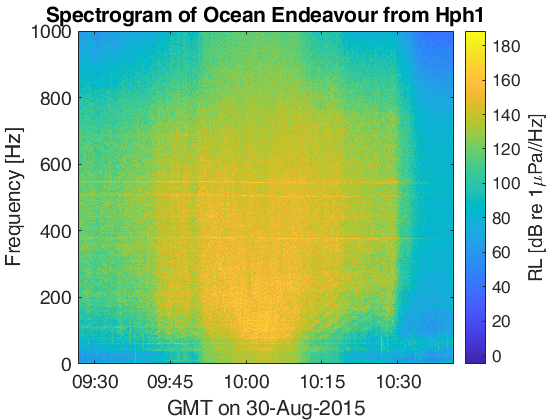

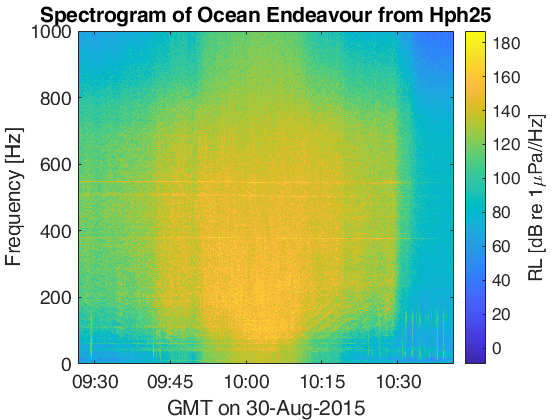

switch tog.plotSpec
    case 'no'
    case 'yes'
        for RecInd=1:24:par.numRec
            figure;
            %RecInd = par.refRecInd;
            %imagesc(TimeVector,fRspectra,10*log10(S{RecInd}).'); dt
            imagesc(TimeVector,fRspectra,20*log10(S{RecInd}).');
            title(['Spectrogram of Ocean Endeavour from Hph' num2str(RecInd)],'FontSize',par.fontSize)
            axis xy;
            h = colorbar;%caxis([50 130])
            set(get(h,'ylabel'),'string','RL [dB re 1\muPa//Hz]',...
                'FontSize',par.fontSize);
            datetick('x','keeplimits');
            xlabel(['GMT on ' datestr(TimeVector(1),'dd-mmm-yyyy')],...
                'FontSize',par.fontSize)
            ylabel('Frequency [Hz]','FontSize',par.fontSize)
            ylim([0 1000])
            set(gca, 'FontSize',par.fontSize)
            %xline(TimeVector(gainStart+2),'g'); xline(TimeVector(gainEnd),'r'); xline(TimeVector(gainEnd-gain.step2lead),'g');
        end
end

## Plot average spectra

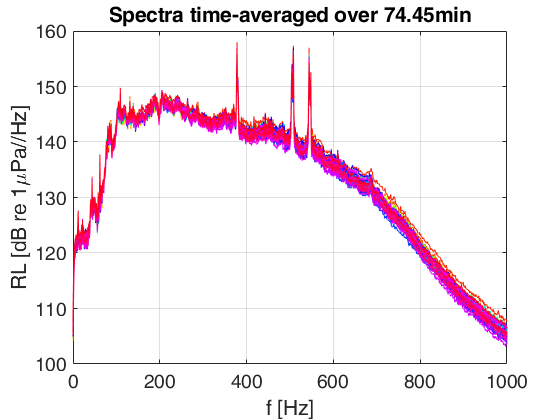

switch tog.plotSpectra
    case 'no'
    case 'yes'
        figure
        colorarray = hsv(par.numRec);
        for RecInd=1:par.numRec
            plot(fRspectra,20*log10(sum(S{RecInd})/NumSpec),...
                'Color',colorarray(RecInd,:));
            hold on
        end
        grid on
        title(['Spectra time-averaged over '...
            num2str((TimeVector(end)-TimeVector(1))*24*60) 'min'],'FontSize',par.fontSize)
        ylabel('RL [dB re 1\muPa//Hz]','FontSize',par.fontSize)
        xlabel('f [Hz]','FontSize',par.fontSize)
        set(gca, 'FontSize',par.fontSize)
        %ylim([100 170])
        xlim([0 1000])
end

## Compute received levels

The squared received sound pressures for each hph are reported on a relative logarithmic scale in dB with a reference pressure of 1 uPa^2 and are referred to as received levels (RLs)

RLship = zeros(par.numRec,NumSpec-2);       %broad band received level [dB]

for RecInd = 1:par.numRec
    for index=1:NumSpec-2
        %compute source level from spectrum for beam angle
        RLship(RecInd,index) = 20*log10(trapz(fRspectra(par.fstartind:par.fStopInd),...
            (S{RecInd}(index,par.fstartind:par.fStopInd))));%...
    end
end
RLship = RLship';
%RLship = (RLship+gain.total)';

## Spatial data processing

#### Load array locations

load arrays_lat-long
% array1=table2array(array1(:,1:3));
% array2=table2array(array2(:,1:3));
A{1}=table2cell(array1);
A{2}=table2cell(array2);

### Load AIS file

Load - sync to spec - calc TL

m = matfile('byShip.mat');
switch tog.VOI
    case {'OcEnd-AAA1-30Aug', 'OcEnd-AAA2-30Aug', 'OcEnd-AAA1-31Aug', 'OcEnd-AAA2-31Aug'}
        AIS = m.Oc_End;
    case 'HebSky-AAA2-26Aug'
        AIS = m.Heb_Sky;
    case {'Lat-AAA1-02Sep', 'Lat-AAA2-02Sep', 'Lat-AAA1-03Sep', 'Lat-AAA2-03Sep'}
        AIS = m.Latitude;
end
AIS = sortrows(AIS,'datetime','ascend');
mmsi = AIS.mmsi(1);
AIS.mmsi = []; AIS.rate_of_turn = []; AIS.hdg = [];  % eliminate unused vars
AIStime = table2timetable(AIS);  % might need to make all of this a structure
AIStimeRange = timerange((startTime),(endTime-seconds(6)));  %because integration periods
AIStime = AIStime(AIStimeRange,:);

### Synchronize spectral and spatial data

Make RL and TL same length and combine in time 

timeVector = datetime(TimeVector(1:length(S{1}(:,1))),'ConvertFrom','datenum')';
RLtime = timetable(timeVector,RLship);
SPL = synchronize(RLtime,AIStime,'regular','linear','TimeStep',seconds(3)); %'KeepOriginalTimes',true
SPL = SPL(1:height(RLtime),:); %[RLsync,AISsync] = synchronize(RLtime,AIStime,'regular','linear','TimeStep',seconds(30));

### Calculate ranges along ship track

% [R1,R2] = calcDist(SPL.lat, SPL.long, array1(:,1:2), array2(:,1:2));
% SPL = addvars(SPL,R1,R2);
[R1,R2] = calcDist(SPL.lat, SPL.long, [array1.lat array1.long], [array2.lat array2.long]);
SPL = addvars(SPL,R1,R2);

### Calculate CPA range and time

[rangeCPA_1,timeCPA_1] = min(R1(:,1,1));
[rangeCPA_2,timeCPA_2] = min(R2(:,1,1));
specCPA = 'CPA range AAA1 = %4.2f km and AAA2 = %4.2f km';
fprintf(specCPA,rangeCPA_1,rangeCPA_2);

CPA range AAA1 = 2.04 km and AAA2 = 1.33 km

### Plot ship track vs array

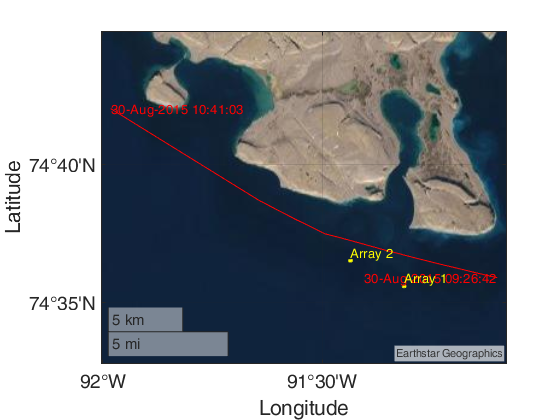

switch tog.plotShipTrack
    case 'no'
    case 'yes'
        figure
        geoplot([SPL.lat], [SPL.long],'r-',...
            [array2.lat],[array2.long],'y.',...
            [array1.lat],[array1.long],'y.')
        text(SPL.lat(1),SPL.long(1),datestr(SPL.timeVector(1)),...
            'HorizontalAlignment','right',"Color",'r');
        text(SPL.lat(end),SPL.long(end),datestr(SPL.timeVector(end)),...
            'HorizontalAlignment','left',"Color",'r');
        text(array1.lat(1),array1.long(1),'Array 1',...
            'VerticalAlignment','bottom',"Color",'y');
        text(array2.lat(1),array2.long(1),'Array 2',...
            'VerticalAlignment','bottom',"Color",'y');
        set(gca, 'FontSize',par.fontSize)
        %geobasemap colorterrain
        %[SPL.lat], [SPL.long],'b*',...
        geobasemap satellite
end

### Plot bearing histogram of ranges

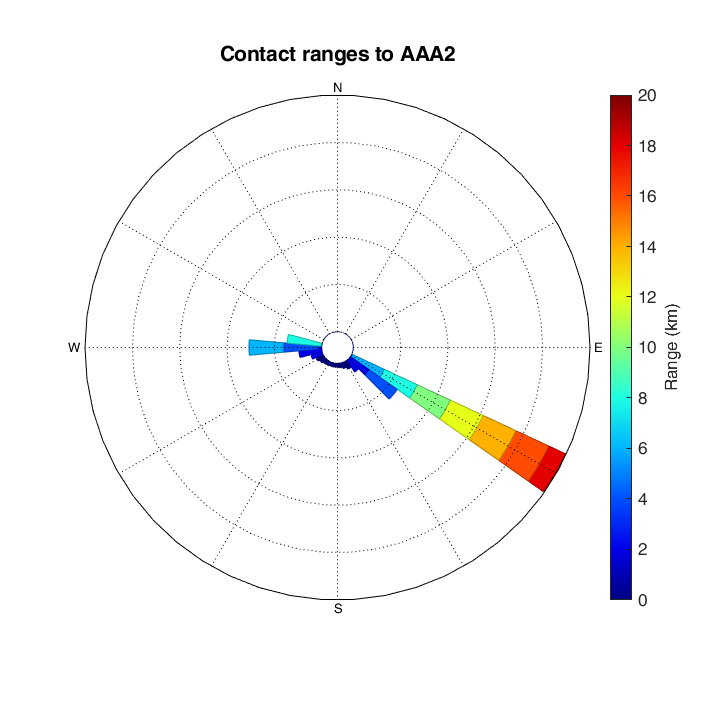

switch tog.plotBearingHistory
    case 'no'
    case 'yes'
        switch AOI
            case 'AAA1'
                rangeRoser(R1(:,1,2), R1(:,1,1), 'legendtype', 1, 'anglenorth', 0, 'angleeast', 90, 'lablegend', 'Distance (km)');
            case 'AAA2'
                rangeRoser(R2(:,1,2), R2(:,1,1), 'legendtype', 1, 'anglenorth', 0, 'angleeast', 90, 'lablegend', 'Distance (km)');
        end
        set(gca,'FontSize',14); title({['Contact ranges to ' AOI] [' ']});
        h = colorbar; ylabel(h, 'Range (km)')
end

#### Determine look angle (aspect)

SPL.aspect2 = wrapTo360(SPL.crs - SPL.R2(:,:,2));
SPL.rads2 = deg2rad(SPL.aspect2);
SPL.aspect1 = wrapTo360(SPL.crs - SPL.R1(:,:,2));
SPL.rads1 = deg2rad(SPL.aspect1);
switch AOI
    case 'AAA1'
        SPL.rads = SPL.rads1;
    case 'AAA2'
        SPL.rads = SPL.rads2;
end

### Plot ship aspects over track

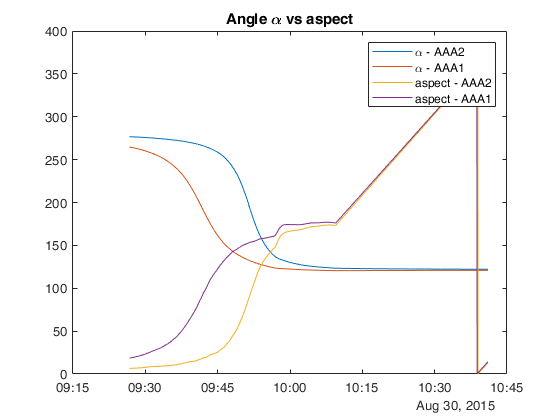

switch tog.plotAspects
    case 'no'
    case 'yes'
        figure
        plot(SPL.timeVector,SPL.R2(:,par.refRecInd,2))
        hold on
        plot(SPL.timeVector,SPL.R1(:,par.refRecInd,2))
        plot(SPL.timeVector,SPL.aspect2(:,par.refRecInd))
        plot(SPL.timeVector,SPL.aspect1(:,par.refRecInd))
        title({'Angle \alpha vs aspect'})
        legend('\alpha - AAA2','\alpha - AAA1','aspect - AAA2','aspect - AAA1')
end

### Plot time resolution of AIS data, speed and range history of contact

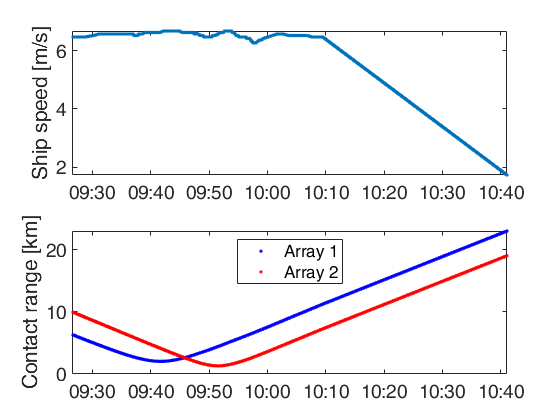

switch tog.plotSpatialSummary
    case 'no'
    case 'yes'
        figure
        %         subplot(3,1,1)
        %         plot(AIStime.datetime(1:end-1),diff(AIStime.datetime),'.');
        %         datetick('x')
        %         ylabel('AIS refresh [s]'), ylim([min(diff(AIStime.datetime))])
        subplot(2,1,1)
        plot(SPL.timeVector,par.kts2ms*SPL.speed_over_ground,'.');
        datetick('x'), xlim([min(SPL.timeVector) max(SPL.timeVector)])
        ylabel('Ship speed [m/s]');%, ylim([6 7])
        set(gca,'FontSize',14)
        subplot(2,1,2)
        plot(SPL.timeVector,R1(:,par.refRecInd,1),'.b');
        hold on
        plot(SPL.timeVector,R2(:,par.refRecInd,1),'.r')
        datetick('x'), xlim([min(SPL.timeVector) max(SPL.timeVector)])
        ylabel('Contact range [km]') %, ylim([0 20])
        legend('Array 1','Array 2','Location','north')
        set(gca,'FontSize',14)
end

### Transform AIS lats/longs to x-y   

SPL.vx = zeros(height(SPL),1);
SPL.vy = zeros(height(SPL),1);
SPL.v = zeros(height(SPL),1);

[SPL.x, SPL.y] = latlon2xy(SPL.lat,SPL.long,...
    array2.lat(par.refRecInd),array2.long(par.refRecInd));

[array1.x, array1.y] = latlon2xy(array1.lat(:),array1.long(:),...
    array2.lat(par.refRecInd),array2.long(par.refRecInd));
[array2.x, array2.y] = latlon2xy(array2.lat(:),array2.long(:),...
    array2.lat(par.refRecInd),array2.long(par.refRecInd));
arrays = [array1.x array1.y -1/par.km2m*array1.depth];
arrays(:,:,2) = [array2.x array2.y -1/par.km2m*array2.depth];  %negative depth

### Calculate x and y components of ship speed

SPL.vx(1:end-1) = diff(SPL.x)./(diff(datenum(SPL.timeVector)*24*3600)); %km/s
SPL.vx(end) = SPL.vx(end-1);
SPL.vy(1:end-1) = diff(SPL.y)./(diff(datenum(SPL.timeVector)*24*3600)); %km/s
SPL.vx(end) = SPL.vx(end-1);
SPL.v = sqrt(SPL.vx.^2 + SPL.vy.^2); %km/s

### Plot Interpolated Track

funPlotIntTrack(SPL, par, TimeVector, tog.plotIntTrack);

### Compute radiation pattern

alpha = zeros(par.numRec,NumSpec-2,par.nArrays);        %horizontal angle [deg]
phi = zeros(par.numRec,NumSpec-2,par.nArrays);          %vertical angle [deg]
R = zeros(par.numRec,NumSpec-2,par.nArrays);            %slant range [m]
SL.broadband = zeros(par.numRec,NumSpec-2); %broadband source level [dB]
SL.ALL = cell(par.numRec,1);                %source spectra level [dB]

for RecInd = 1:par.numRec
    for index=1:NumSpec-2
        for arrayIndex = 1:par.nArrays
            
            %compute beam angles alpha and phi
            thetax=0;               % roll angle of Zc =  rotates beampattern around (0deg,0deg)
            thetay = 0;
            thetaz = atan2(SPL.vy(index),SPL.vx(index));
            Rx = [1 0 0; 0 cos(thetax) sin(thetax); 0 -sin(thetax) cos(thetax)];
            Ry = [cos(thetay) 0 sin(thetay); 0 1 0; -sin(thetay) 0 cos(thetay)];
            Rz = [cos(thetaz) sin(thetaz) 0; -sin(thetaz) cos(thetaz) 0; 0 0 1];
            b = arrays(RecInd,:,arrayIndex)...
                - [SPL.x(index) SPL.y(index) 0];
            bprime = Rx*Ry*Rz*b.';
            
            alpha(RecInd,index,arrayIndex) =180*atan2(bprime(2),bprime(1))/pi;
            phi(RecInd,index,arrayIndex) = 180*atan2(bprime(3),norm(bprime(1:2)))/pi;
            
            %slant range of each ship location
            R(RecInd,index,arrayIndex) = sqrt((SPL.x(index)-arrays(RecInd,1,arrayIndex)).^2 + ...
                (SPL.y(index)-arrays(RecInd,2,arrayIndex)).^2 + arrays(RecInd,3,arrayIndex).^2);
            
            %compute source level from spectrum for beam angle
            SL.broadband(RecInd,index) = ...
                RLship(index,RecInd) + par.spread*log10(R(RecInd,index,arrayIndex));  %SL = RL + TL
            SL.ALL{RecInd}(index,:) = ...
                20*log10(S{RecInd}(index,:))+par.spread*log10(R(RecInd,index,arrayIndex));
        end
    end
end


### Calculate spread over hydrophones

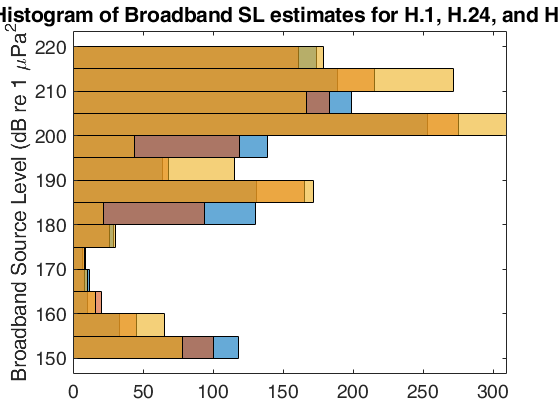

funPlotSPLHist(par, SL);

## Investigate lobing pattern

### Separate into 'look' windows (bins) and calculate mean / std

% means.bins = linspace(min(min(SPL.rads)),max(max(SPL.rads)),par.nSLbins);
% [bincounts, binidx] = histc(SPL.rads, means.bins);
%
% for i = 1:par.nSLbins
%     means.broadband(i) = mean(SL.broadband(binidx' == i))
%     stddev.broadband(i) = std(SL.broadband(binidx' == i))
% end

### Plot broadband scatterplot

% figure
% polarpattern(SPL.aspect2,SPL.SL2,'TitleTop', 'Radiated noise pattern (dB)')
figure
polarscatter(SPL.rads(:,1)',SL.broadband(1,:),'.')
rlim(par.bbLim)
%[min(min(SL.broadband))-par.scale max(max(SL.broadband))]
%thetalim([min(SPL.rads(:,1)) max(SPL.rads(:,1))])
title({'Radiated broadband noise pattern'},'FontSize',par.fontSize)
if par.numRec == 48
    hold on
    for RecInd=2:par.scatInt:par.numRec
        polarscatter(SPL.rads(:,RecInd)',SL.broadband(RecInd,:),'.')
    end
end
ax = gca;
rruler = ax.RAxis;
rruler.Label.String = 'dB re: 1\muPa @ 1m';
ax.FontSize = par.fontSize;

#### Polar plot of mean values for lobing

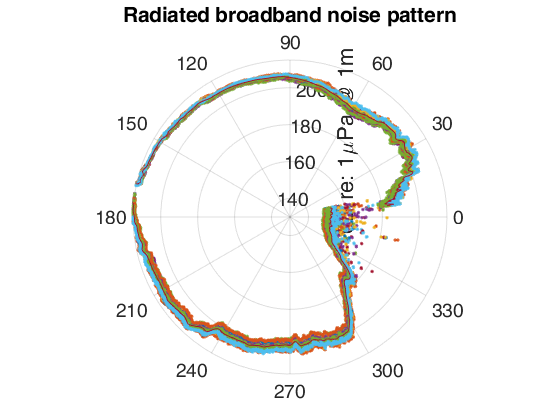

switch tog.plotMeans
    case 'no'
    case 'yes'
        hold on
        %polarplot(means.bins,means.broadband,'LineWidth',par.lineWidth)
        polarplot(SPL.rads(:,24)',smoothdata(mean(SL.broadband),'gaussian',par.smooth),'LineWidth',par.lineWidth)
end

#### Plot SL variance over time

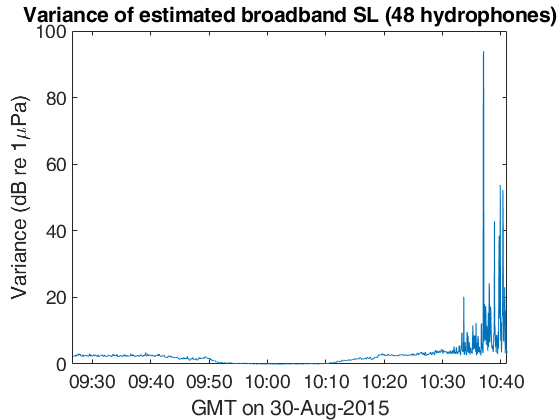

figure
plot(SPL.timeVector,var(SL.broadband))
xlim([min(SPL.timeVector) max(SPL.timeVector)]);
datetick('x','keeplimits');
title('Variance of estimated broadband SL (48 hydrophones)')
xlabel(['GMT on ' datestr(TimeVector(1),'dd-mmm-yyyy')]);
ylabel('Variance (dB re 1\muPa)');
%ylim([0 3])
set(gca,'FontSize',par.fontSize)

### Plot narrowband lobing pattern for tonals

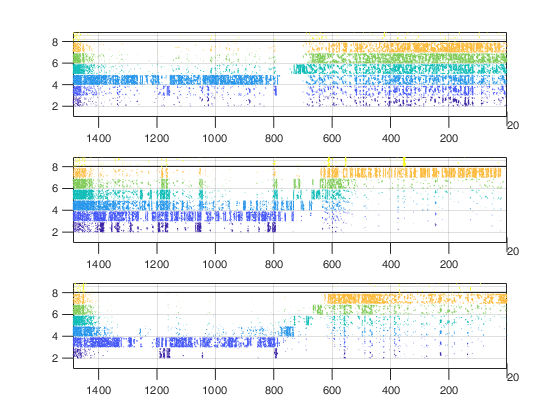

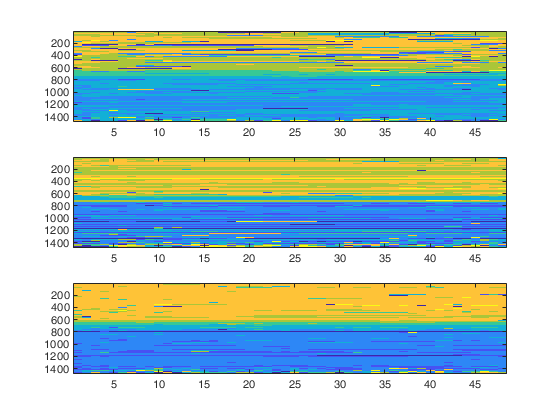

switch tog.VOI
    case {'OcEnd-AAA1-30Aug','OcEnd-AAA2-30Aug'}
        int.tonal1 = 376:383;  % C52
        int.tonal2 = 503:510; % S185
        int.tonal3 = 543:550;  % C75
    case {'OcEnd-AAA1-31Aug','OcEnd-AAA2-31Aug'}
        int.tonal1 = 363:373;
        int.tonal2 = 504:514;
        int.tonal3 = 526:536;
    case 'HebSky-AAA2-26Aug'
        int.tonal1 = 230:238;
        int.tonal2 = 463:473;
        int.tonal3 = 596:605;
    case {'Lat-AAA1-02Sep','Lat-AAA2-02Sep','Lat-AAA1-03Sep','Lat-AAA2-03Sep'}
        int.tonal1 = 77:84;     %C24
        int.tonal2 = 120:126;   %C36
        int.tonal3 = 132:139;   %C40
        
end
tonal1.max = zeros(NumSpec-2,par.numRec);
tonal1.idx = zeros(NumSpec-2,par.numRec);
tonal2.max = zeros(NumSpec-2,par.numRec);
tonal2.idx = zeros(NumSpec-2,par.numRec);
tonal3.max = zeros(NumSpec-2,par.numRec);
tonal3.idx = zeros(NumSpec-2,par.numRec);

for RecInd = 1:par.numRec
    p = SL.ALL{RecInd,1}(:,int.tonal1);
    [tonal1.max(:,RecInd),tonal1.idx(:,RecInd)] = max(p,[],2);
    p = SL.ALL{RecInd,1}(:,int.tonal2);
    [tonal2.max(:,RecInd),tonal2.idx(:,RecInd)] = max(p,[],2);
    p = SL.ALL{RecInd,1}(:,int.tonal3);
    [tonal3.max(:,RecInd),tonal3.idx(:,RecInd)] = max(p,[],2);
end

switch tog.plotTonalTracker
    case 'no'
    case 'yes'
        figure
        subplot(3,1,1)
        contour3(tonal1.idx);
        view(gca,[-90 -7.2]);
        subplot(3,1,2)
        contour3(tonal2.idx);
        view(gca,[-90 -7.2]);
        subplot(3,1,3)
        contour3(tonal3.idx);
        view(gca,[-90 -7.2]);
        figure
        subplot(3,1,1)
        imagesc(tonal1.idx);
        subplot(3,1,2)
        imagesc(tonal2.idx);
        subplot(3,1,3)
        imagesc(tonal3.idx);
end

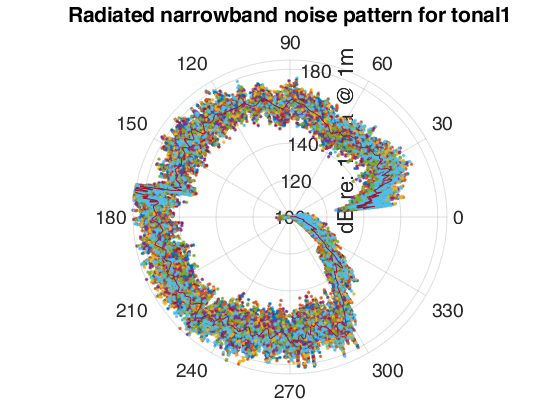



% for i = 1:par.nSLbins
%     means.tonal1(i) = mean(tonal1.max(binidx' == i))
%     stddev.tonal1(i) = std(tonal1.max(binidx' == i))
%     means.tonal2(i) = mean(tonal2.max(binidx' == i))
%     stddev.tonal2(i) = std(tonal2.max(binidx' == i))
%     means.tonal3(i) = mean(tonal3.max(binidx' == i))
%     stddev.tonal3(i) = std(tonal3.max(binidx' == i))
% end

figure
%subplot(1,3,1)
polarscatter(SPL.rads(:,1),tonal1.max(:,1),'.')
rlim(par.nbLim)
%thetalim([0 180])
%rlim([min(min(tonal1.max))-par.scale max(max(tonal1.max))+par.scale])
title({'Radiated narrowband noise pattern for tonal1'})
if par.numRec == 48
    hold on
    for RecInd=2:par.scatInt:par.numRec
        polarscatter(SPL.rads(:,RecInd)',tonal1.max(:,RecInd),'.')
    end
    %legend('H.1','H.12','H.24','H.36','H.48','Location','south')
end
ax = gca;
rruler = ax.RAxis;
rruler.Label.String = 'dB re: 1\muPa @ 1m';
ax.FontSize = par.fontSize;
hold on
%polarplot(means.bins,means.tonal1,'LineWidth',par.lineWidth)
polarplot(SPL.rads(:,24)',smoothdata(mean(tonal1.max,2),'gaussian',par.smooth),'LineWidth',par.lineWidth)

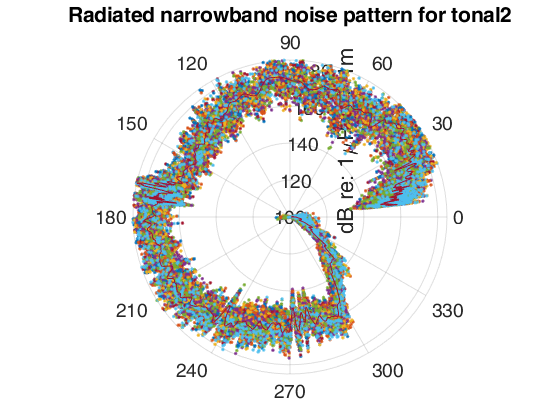


figure
%subplot(1,3,2)
polarscatter(SPL.rads(:,1),tonal2.max(:,1),'.')
rlim(par.nbLim)
%thetalim([0 180])
%rlim([min(min(tonal2.max))-par.scale max(max(tonal2.max))])
title({'Radiated narrowband noise pattern for tonal2'})
if par.numRec == 48
    hold on
    for RecInd=2:par.scatInt:par.numRec
        polarscatter(SPL.rads(:,RecInd)',tonal2.max(:,RecInd),'.')
    end
    %legend('H.1','H.12','H.24','H.36','H.48','Location','south')
end
ax = gca;
rruler = ax.RAxis;
rruler.Label.String = 'dB re: 1\muPa @ 1m';
ax.FontSize = par.fontSize;
hold on
polarplot(SPL.rads(:,24)',smoothdata(mean(tonal2.max,2),'gaussian',par.smooth),'LineWidth',par.lineWidth)

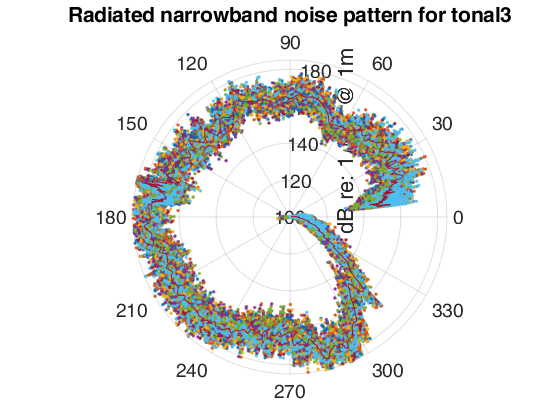

% polarplot(means.bins,means.tonal2,'LineWidth',par.lineWidth)

figure
%subplot(1,3,3)
polarscatter(SPL.rads(:,1),tonal3.max(:,1),'.')
rlim(par.nbLim)
%thetalim([0 180])
%rlim([min(min(tonal3.max))-par.scale max(max(tonal3.max))])
title({'Radiated narrowband noise pattern for tonal3'})
if par.numRec == 48
    hold on
    for RecInd=2:par.scatInt:par.numRec
        polarscatter(SPL.rads(:,RecInd)',tonal3.max(:,RecInd),'.')
    end
    %legend('H.1','H.12','H.24','H.36','H.48','Location','south')
end
ax = gca;
rruler = ax.RAxis;
rruler.Label.String = 'dB re: 1\muPa @ 1m';
ax.FontSize = par.fontSize;
hold on
%polarplot(means.bins,means.tonal3,'LineWidth',par.lineWidth)
polarplot(SPL.rads(:,24)',smoothdata(mean(tonal3.max,2),'gaussian',par.smooth),'LineWidth',par.lineWidth)

%tightenUp;


## Save variables

switch tog.saveOn
    case 'no'
    case 'yes'
        BB = SL.broadband;
        save([tog.VOI '.mat'],'SPL','BB','tonal1','tonal2','tonal3');
end


## Junk

### Plot ship aspects over track

% switch tog.plotAspects
%     case 'no'
%     case 'yes'
%         figure
%         plot(SPL.timeVector,SPL.R2(:,par.refRecInd,2))
%         hold on
%         plot(SPL.timeVector,SPL.R1(:,par.refRecInd,2))
%         plot(SPL.timeVector,SPL.aspect2(:,par.refRecInd))
%         plot(SPL.timeVector,SPL.aspect1(:,par.refRecInd))
%         plot(SPL.timeVector,alpha(par.refRecInd,:,1)')
%         plot(SPL.timeVector,alpha(par.refRecInd,:,2)')
%         title({'Ship-array angle vs ship aspect \alpha (direct and inferred)'})
%         legend('Ship-AAA2','Ship-AAA1','\alpha_d AAA2','\alpha_d AAA1',...
%             '\alpha_i AAA2','\alpha_i AAA1')
% end